normalization_calc_duration = 7.3149

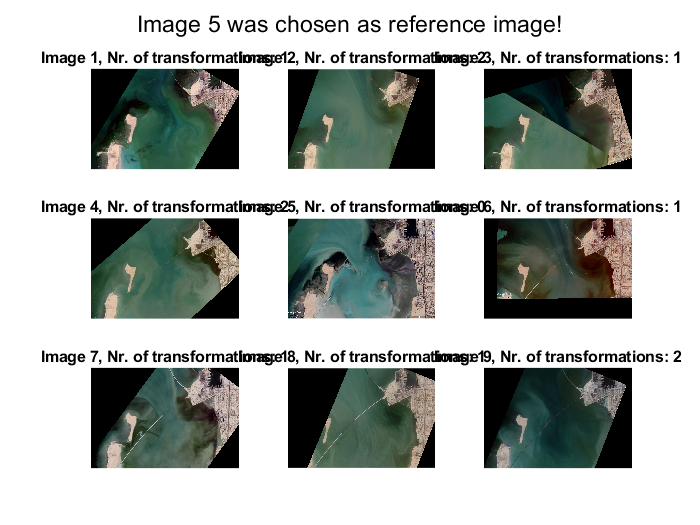

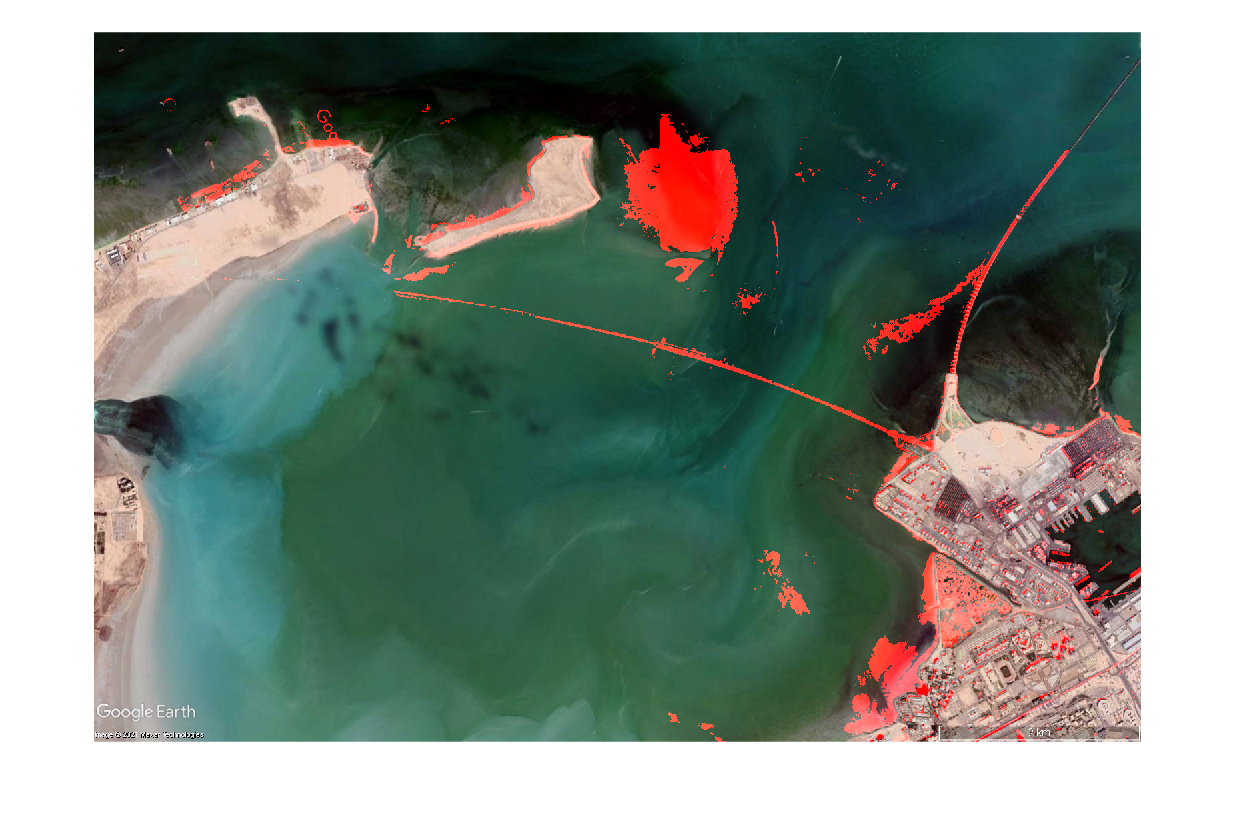

%run the main to obtainreconstructed images in Workspace
Main_CV_SS21;

close all;

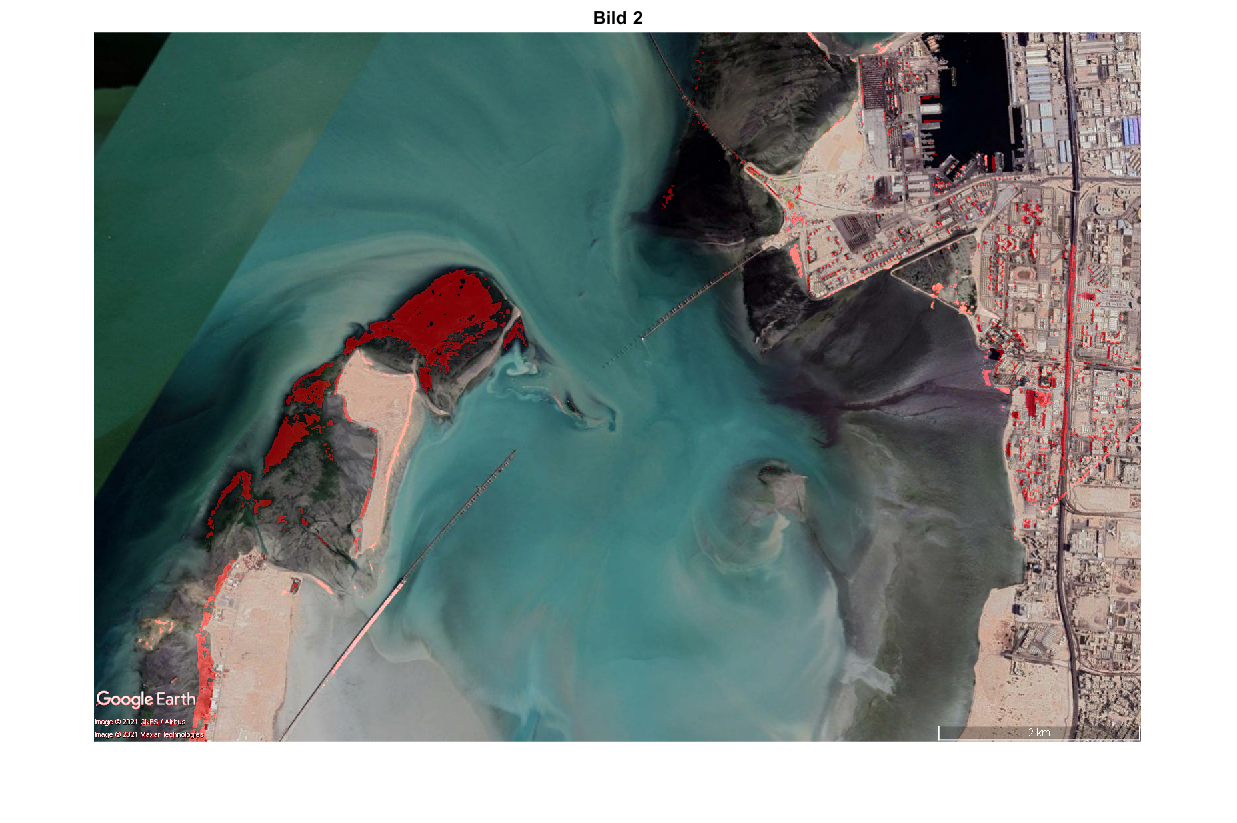


ind1=4;
ind2=5;
tau=0.3;%usually interesting arounfd 0.1-0.5
l=3;%usually interesting in the region from 11 to 155
[I_hl,mask]=Differentiate_size_of_change(Images_reconstructed{ind1},Images_reconstructed{ind2}, tau, l,0.15);
% imshow(I_hl);
% title("Bild 1")
%highliting the actual detailed changes:
[~,mask_detail]=Differentiate_size_of_change(Images_reconstructed{ind1},Images_reconstructed{ind2}, tau, 3, 0.1);
mask_final=mask_detail.*mask;%use the wider filtered image mask to mask detailed one-> size of change is improtant, but details maintained
I_hl2=im2double(Images_reconstructed{ind2});
I_hl2(:,:,1)=I_hl2(:,:,1)+0.5*mask_final;
imshow(I_hl2);
title("Bild 2")


%evaluation:
%works very well for dubai and glacier, but does not detect bridge on
%Kuwait (%too thin)
% %due to missing color equalization: fails